d = inputs;
mp = mesh_points(d.number_of_points_array);


explicit = readmatrix("exports\1D\1000_explicit.csv");
implicit = readmatrix("exports\1D\1000_implicit.csv");

space = linspace(0, d.total_distance, d.number_of_points_array)

space =          0    0.5005    1.0010    1.5015    2.0020    2.5025    3.0030    3.5035    4.0040    4.5045    5.0050    5.5055    6.0060    6.5065    7.0070    7.5075    8.0080    8.5085    9.0090    9.5095   10.0100   10.5105   11.0110   11.5115   12.0120   12.5125   13.0130   13.5135   14.0140   14.5145   15.0150   15.5155   16.0160   16.5165   17.0170   17.5175   18.0180   18.5185   19.0190   19.5195   20.0200   20.5205   21.0210   21.5215   22.0220   22.5225   23.0230   23.5235   24.0240   24.5245


TIME =1600

TIME = 1600

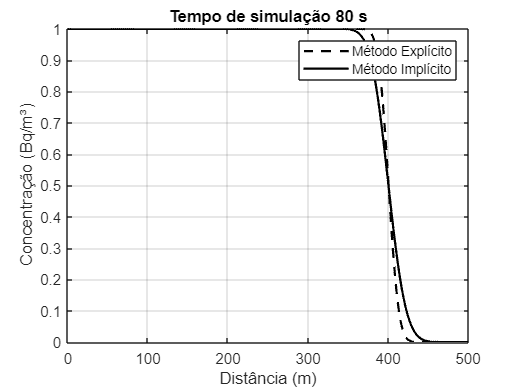

plot(space,explicit(:, TIME), 'k--','LineWidth',1.5);
ylim([0,d.C_x1]);
grid; 

xlabel('Distância (m)'); 
ylabel('Concentração (Bq/m³)');
title("Tempo de simulação " + num2str(TIME*mp.delta_t, 2) + " s");

hold on 

plot(space,implicit(:, TIME), 'k-','LineWidth',1.5);
hold off

legend('Método Explícito', 'Método Implícito')

ERROR_TIME =1300

ERROR_TIME = 1300

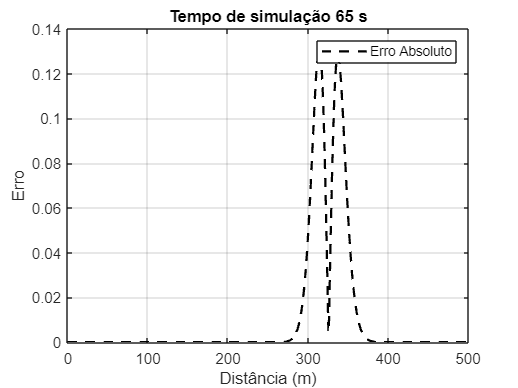

error = abs(explicit - implicit);
% relative_error = error./explicit;
% relative_error(relative_error == -Inf) = 0;

plot(space,error(:, ERROR_TIME), 'k--','LineWidth',1.5);
grid; 

xlabel('Distância (m)'); 
ylabel('Erro');
title("Tempo de simulação " + num2str(ERROR_TIME*mp.delta_t, 2) + " s");

% hold on 
% 
% plot(space,relative_error(:, ERROR_TIME), 'k-','LineWidth',1.5);
% hold off
% 
legend('Erro Absoluto')